% 2.61 
syms cphi sphi ctheta stheta cpsi spsi %% sysms 문자식으로 표현된 연산을 하겠다 
%% y-axis phi, z-axis theta, x-axis psi 

Ry=sym([cphi 0 sphi; 0 1 0; -sphi 0 cphi])

$$Ry = \left(\begin{array}{ccc} \mathrm{cphi} & 0 & \mathrm{sphi}\\ 0 & 1 & 0\\ -\mathrm{sphi} & 0 & \mathrm{cphi} \end{array}\right)$$

Rz=sym([ctheta -stheta 0; stheta ctheta 0; 0 0 1])

$$Rz = \left(\begin{array}{ccc} \mathrm{ctheta} & -\mathrm{stheta} & 0\\ \mathrm{stheta} & \mathrm{ctheta} & 0\\ 0 & 0 & 1 \end{array}\right)$$

Rx=sym([1 0 0; 0 cpsi -spsi; 0 spsi cpsi])

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \mathrm{cpsi} & -\mathrm{spsi}\\ 0 & \mathrm{spsi} & \mathrm{cpsi} \end{array}\right)$$


Rotation = Ry*Rz*Rx %% composite matrix 

$$Rotation = \left(\begin{array}{ccc} \mathrm{cphi}\,\mathrm{ctheta} & \mathrm{sphi}\,\mathrm{spsi}-\mathrm{cphi}\,\mathrm{cpsi}\,\mathrm{stheta} & \mathrm{cpsi}\,\mathrm{sphi}+\mathrm{cphi}\,\mathrm{spsi}\,\mathrm{stheta}\\ \mathrm{stheta} & \mathrm{cpsi}\,\mathrm{ctheta} & -\mathrm{ctheta}\,\mathrm{spsi}\\ -\mathrm{ctheta}\,\mathrm{sphi} & \mathrm{cphi}\,\mathrm{spsi}+\mathrm{cpsi}\,\mathrm{sphi}\,\mathrm{stheta} & \mathrm{cphi}\,\mathrm{cpsi}-\mathrm{sphi}\,\mathrm{spsi}\,\mathrm{stheta} \end{array}\right)$$

Rotation_Matrix_global_coordinate=Rz*Ry*Rx

$$Rotation\_Matrix\_global\_coordinate = \left(\begin{array}{ccc} \mathrm{cphi}\,\mathrm{ctheta} & \mathrm{ctheta}\,\mathrm{sphi}\,\mathrm{spsi}-\mathrm{cpsi}\,\mathrm{stheta} & \mathrm{spsi}\,\mathrm{stheta}+\mathrm{cpsi}\,\mathrm{ctheta}\,\mathrm{sphi}\\ \mathrm{cphi}\,\mathrm{stheta} & \mathrm{cpsi}\,\mathrm{ctheta}+\mathrm{sphi}\,\mathrm{spsi}\,\mathrm{stheta} & \mathrm{cpsi}\,\mathrm{sphi}\,\mathrm{stheta}-\mathrm{ctheta}\,\mathrm{spsi}\\ -\mathrm{sphi} & \mathrm{cphi}\,\mathrm{spsi} & \mathrm{cphi}\,\mathrm{cpsi} \end{array}\right)$$


% example 2.81 


Ryy=[cos(deg2rad(90)) 0 sin(deg2rad(90)); 0 1 0; -sin(deg2rad(90)) 0  cos(deg2rad(90))]%sym([cphi 0 sphi; 0 1 0; -sphi 0 cphi])

Ryy =     0.0000         0    1.0000
         0    1.0000         0
   -1.0000         0    0.0000


Rzz=[cos(deg2rad(90)) -sin(deg2rad(90)) 0; -sin(deg2rad(90)) cos(deg2rad(90)) 0; 0 0 1] %sym([ctheta -stheta 0; stheta ctheta 0; 0 0 1])

Rzz =     0.0000   -1.0000         0
   -1.0000    0.0000         0
         0         0    1.0000


Rxx=[1 0 0;  0 cos(deg2rad(90)) -sin(deg2rad(90)); 0 sin(deg2rad(90)) cos(deg2rad(90))]%sym([1 0 0; 0 cpsi -spsi; 0 spsi cpsi])

Rxx =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000



Rotation11= Ryy*Rzz*Rxx

Rotation11 =     0.0000    1.0000    0.0000
   -1.0000    0.0000   -0.0000
   -0.0000    0.0000   -1.0000




l1=0.432;
l2=0.432; % 로봇팔의 길이 


for i=1:1:3 % i를 1부터 1씩 증가시켜서 3까지 
    theta2=pi/6*i
    theta1=pi/6*i
    x1=l1*cos(theta1)
    y1=l1*sin(theta1)
    
    % forward kinematics
    
    x=l1*cos(theta1)+l2*cos(theta1+theta2)
    y=l1*sin(theta1)+l2*sin(theta1+theta2)
    
    rx=[0,x1,x];
    ry=[0,y1,y];
    plot(rx,ry,'-')
    hold on
    plot(x,y,'*')
       
end

theta2 = 0.5236

theta1 = 0.5236

x1 = 0.3741

y1 = 0.2160

x = 0.5901

y = 0.5901

theta2 = 1.0472

theta1 = 1.0472

x1 = 0.2160

y1 = 0.3741

x = 1.3878e-16

y = 0.7482

theta2 = 1.5708

theta1 = 1.5708

x1 = 2.6452e-17

y1 = 0.4320

x = -0.4320

y = 0.4320

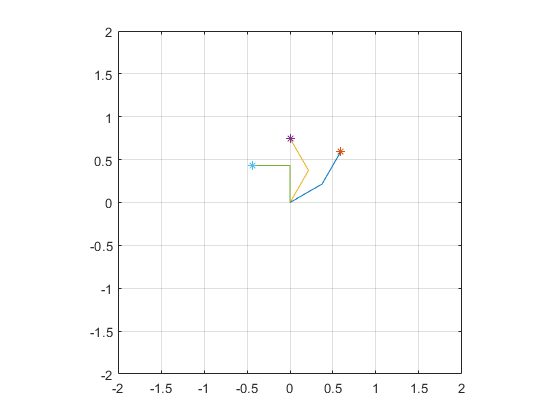


    

hold off
axis([-2, 2 -2,2])
axis('square')
grid on 

% example 3.2 

l1=0.432;
l2=0.432; % 로봇팔의 길이 


for i=1:1:3 % i를 1부터 1씩 증가시켜서 3까지 
    theta2=pi/6*i
    theta1=pi/6*i
    x1=l1*cos(theta1)
    y1=l1*sin(theta1)
    
    % forward kinematics
    
    x=l1*cos(theta1)+l2*cos(theta1+theta2)
    y=l1*sin(theta1)+l2*sin(theta1+theta2)
    
    rx=[0,x1,x];
    ry=[0,y1,y];
    plot(rx,ry,'-')
    hold on
    plot(x,y,'*')
       
end

theta2 = 0.5236

theta1 = 0.5236

x1 = 0.3741

y1 = 0.2160

x = 0.5901

y = 0.5901

theta2 = 1.0472

theta1 = 1.0472

x1 = 0.2160

y1 = 0.3741

x = 1.3878e-16

y = 0.7482

theta2 = 1.5708

theta1 = 1.5708

x1 = 2.6452e-17

y1 = 0.4320

x = -0.4320

y = 0.4320


    

hold off
axis([-2, 2 -2,2])
axis('square')
grid on 

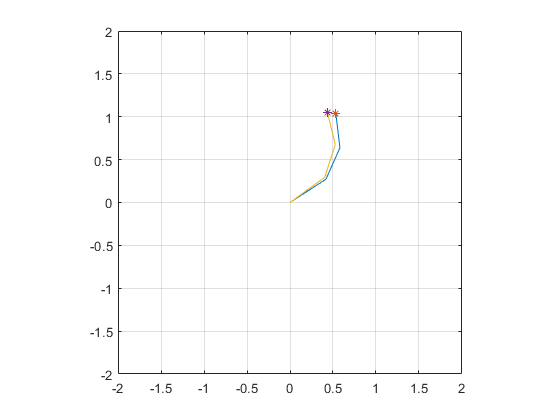

% example 3.3
clear all
clc

l1=0.5;
l2=0.4; % 로봇팔의 길이 
l3=0.3; % 로봇팔의 길이 


for i=1:1:2 % i를 1부터 1씩 증가시켜서 20까지 
    theta3=pi/6+pi/60*i;
    theta2=pi/6+pi/60*i;
    theta1=pi/6+pi/60*i;
    rrrx=l1*cos(theta1);
    rrry=l1*sin(theta1);
    rrx=l1*cos(theta1)+l2*cos(theta1+theta2);
    rry=l1*sin(theta1)+l2*sin(theta1+theta2);
    
    % forward kinematics
    x=l1*cos(theta1)+l2*cos(theta1+theta2)+l3*cos(theta1+theta2+theta3);
    y=l1*sin(theta1)+l2*sin(theta1+theta2)+l2*sin(theta1+theta2+theta3);
    
    rx=[0,rrrx,rrx,x];
    ry=[0,rrry,rry,y];
    plot(rx,ry,'-')
    hold on
    plot(x,y,'*')
       
end

    

hold off
axis([-2, 2 -2,2])
axis('square')
grid on 

% example 3.5 % inverse kinematics 
clear all
clc

l1=0.5;
l2=0.4; % 로봇팔의 길이 
l3=0.3; % 로봇팔의 길이 


for i=1:1:2 % i를 1부터 1씩 증가시켜서 20까지 
    theta3=pi/6+pi/60*i;
    theta2=pi/6+pi/60*i;
    theta1=pi/6+pi/60*i;
    phi=theta1+theta2+theta3
    rrrx=l1*cos(theta1);
    rrry=l1*sin(theta1);
    rrx=l1*cos(theta1)+l2*cos(theta1+theta2);
    rry=l1*sin(theta1)+l2*sin(theta1+theta2);
    
    % forward kinematics
    x=l1*cos(theta1)+l2*cos(theta1+theta2)+l3*cos(theta1+theta2+theta3);
    y=l1*sin(theta1)+l2*sin(theta1+theta2)+l2*sin(theta1+theta2+theta3);
%     
     rx=[0,rrrx,rrx,x];
     ry=[0,rrry,rry,y];
     plot(rx,ry,'-')
     hold on
     plot(x,y,'*')
    
    %% inverse kinematics 
    A=(rrx^2+rry^2-(l1^2+l2^2))/(2*l1*l2)
    th2=atan2(sqrt(1-A^2),A);
    B=[-l2*sin(th2) (l1+l2*cos(th2)); (l1+l2*cos(th2)) l2*sin(th2)]
    sc=inv(B)*[rrx rry]';
    th1=(atan2(sc(1,1),sc(2,1)))
    th3=phi-th1-th2
    xi=l1*cos(th1)+l2*cos(th1+th2)+l3*cos(th1+th2+th3);
    yi=l1*sin(th2)+l2*sin(th1+th2)+l2*sin(th1+th2+th3);
    plot(x,y,'d')
    hold on 
end

phi = 1.7279

A = 0.8387

B =    -0.2179    0.8355
    0.8355    0.2179


th1 = 0.5760

th3 = 0.5760

phi = 1.8850

A = 0.8090

B =    -0.2351    0.8236
    0.8236    0.2351


th1 = 0.6283

th3 = 0.6283

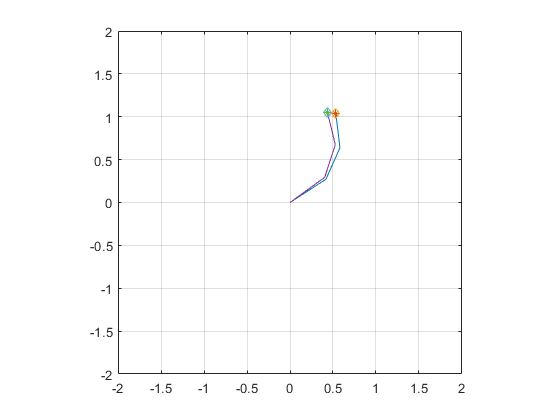


    

hold off
axis([-2, 2 -2,2])
axis('square')
grid on 

% example 4.1 

syms l1 l2 q1 q2
x=l1*cos(q1)+l2*cos(q1+q2);
y=l1*sin(q1)+l2*sin(q1+q2);
J=jacobian([x,y],[q1,q2])

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

det(J)

$$ans = l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{1}\right)-l_{1}\,l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)$$

simplify(J)

$$ans = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$